## Analyse how the CICE grid works

### CICE history grid

clear all
ncdisp('/Users/noahday/Github/cice-dirs/runs/test/history/iceh_ic.2005-01-01-03600.nc')

Source:
           /Users/noahday/GitHub/cice-dirs/runs/test/history/iceh_ic.2005-01-01-03600.nc
Format:
           classic
Global Attributes:
           title       = 'sea ice model output for CICE'
           contents    = 'Diagnostic and Prognostic Variables'
           source      = 'Los Alamos Sea Ice Model, CICE_6.2.0'
           comment     = 'This year has 365 days'
           comment2    = 'File written on model date 20050101'
           comment3    = 'seconds elapsed into model date:   3600'
           conventions = 'CF-1.0'
           history     = 'This dataset was created on 2022-06-09 at 14:15:12.9'
           io_flavor   = 'io_netcdf'
Dimensions:
           d2        = 2
           ni        = 320
           nj        = 384
           nc        = 5
           nkice     = 7
           nksnow    = 1
           nkbio     = 3
           nkaer     = 5
           time      = 1     (UNLIMITED)
           nvertices = 4
           nf        = 12
Variables:
    time        
      

% CICE history grid
grid.cice_hist.lat = ncread('/Users/noahday/Github/cice-dirs/runs/test/history/iceh_ic.2005-01-01-03600.nc',"ULAT");
grid.cice_hist.lon = ncread('/Users/noahday/Github/cice-dirs/runs/test/history/iceh_ic.2005-01-01-03600.nc',"ULON");


### CICE bathymetry

ncdisp('/Users/noahday/Github/cice-dirs/input/CICE_data/grid/gx1/global_gx1.bathy.nc')

Source:
           /Users/noahday/GitHub/cice-dirs/input/CICE_data/grid/gx1/global_gx1.bathy.nc
Format:
           classic
Global Attributes:
           title     = 'ocean bathymetry for grounding scheme'
           source    = 'created from bathy_ORCA025_LIM.std'
           history   = 'Mon Oct 29 16:01:01 2018: ncatted -a source,global,o,c,created from bathy_ORCA025_LIM.std gx1_bathyTP10.nc gx1_bathyTP11.nc
                       Mon Oct 29 16:00:02 2018: ncatted -a contents,global,d,, gx1_bathyTP9.nc gx1_bathyTP10.nc
                       Mon Oct 29 15:59:40 2018: ncatted -a comment,global,d,, gx1_bathyTP8.nc gx1_bathyTP9.nc
                       Mon Oct 29 15:59:33 2018: ncatted -a comment2,global,d,, gx1_bathyTP7.nc gx1_bathyTP8.nc
                       Mon Oct 29 15:59:26 2018: ncatted -a comment3,global,d,, gx1_bathyTP6.nc gx1_bathyTP7.nc
                       Mon Oct 29 15:59:13 2018: ncatted -a conventions,global,d,, gx1_bathyTP5.nc gx1_bathyTP6.nc
                       M

grid.cice_bathy.lat = ncread('/Users/noahday/Github/cice-dirs/input/CICE_data/grid/gx1/global_gx1.bathy.nc',"TLAT");
grid.cice_bathy.lon = ncread('/Users/noahday/Github/cice-dirs/input/CICE_data/grid/gx1/global_gx1.bathy.nc',"TLON");


### ACCESS-OM2 grid

ncdisp('/Users/noahday/Github/cice-dirs/input/CICE_data/grid/om2_1deg/access-om2_1deg.nc')

Source:
           /Users/noahday/GitHub/cice-dirs/input/CICE_data/grid/om2_1deg/access-om2_1deg.nc
Format:
           netcdf4_classic
Global Attributes:
           filename  = 'ocean_grid.nc'
           title     = 'MOM5'
           grid_type = 'regular'
           grid_tile = 'N/A'
Dimensions:
           xt_ocean = 360
           yt_ocean = 300
           time     = 1     (UNLIMITED)
           xu_ocean = 360
           yu_ocean = 300
Variables:
    xt_ocean  
           Size:       360x1
           Dimensions: xt_ocean
           Datatype:   double
           Attributes:
                       long_name      = 'tcell longitude'
                       units          = 'degrees_E'
                       cartesian_axis = 'X'
    yt_ocean  
           Size:       300x1
           Dimensions: yt_ocean
           Datatype:   double
           Attributes:
                       long_name      = 'tcell latitude'
                       units          = 'degrees_N'
                       cart

% ACCESS-OM2 history grid
%grid.access.lat = ncread('/Users/noahday/Github/cice-dirs/input/CICE_data/grid/om2_1deg/access-om2_1deg.nc',"geolat_c");
%grid.access.lon = ncread('/Users/noahday/Github/cice-dirs/input/CICE_data/grid/om2_1deg/access-om2_1deg.nc',"geolon_c");

grid.access.lat = ncread('/Users/noahday/Github/cice-dirs/input/CICE_data/grid/om2_1deg/icegrid.nc',"ulat")*360/(2*pi);
grid.access.lon = ncread('/Users/noahday/Github/cice-dirs/input/CICE_data/grid/om2_1deg/icegrid.nc',"ulon")*360/(2*pi)+180;



ncdisp('/Users/noahday/Github/cice-dirs/input/CICE_data/grid/om2_1deg/om2_1deg_basinmask_yu_xu.nc')

Source:
           /Users/noahday/GitHub/cice-dirs/input/CICE_data/grid/om2_1deg/om2_1deg_basinmask_yu_xu.nc
Format:
           netcdf4
Dimensions:
           yu_ocean = 300
           xu_ocean = 360
Variables:
    yu_ocean
           Size:       300x1
           Dimensions: yu_ocean
           Datatype:   double
           Attributes:
                       _FillValue = NaN
    xu_ocean
           Size:       360x1
           Dimensions: xu_ocean
           Datatype:   double
           Attributes:
                       _FillValue = NaN
    basin   
           Size:       360x300
           Dimensions: xu_ocean,yu_ocean
           Datatype:   int32
           Attributes:
                       long_name = 'basin mask'
                       history   = 'Created by Mark Collier CSIRO YYYY-MM-DD=2021-11-12 HH-MM-SS=10-11-48 basin identifiers: #1 southern ocean, #2 atlantic basin, #3 pacific basin, #4 arctic sea, #5 indian basin, #6 mediterranean, #7 black, #8 hudson bay, #9 baltic sea,


% Bathymetry files
grid.access_bathy.lat = ncread('/Users/noahday/Github/cice-dirs/input/CICE_data/grid/om2_1deg/access-om2_1deg.nc',"geolat_c");
grid.access_bathy.lon = ncread('/Users/noahday/Github/cice-dirs/input/CICE_data/grid/om2_1deg/access-om2_1deg.nc',"geolon_c");


ncdisp('/Users/noahday/Github/cice-dirs/input/CICE_data/grid/om2_1deg/icegrid.nc')

Source:
           /Users/noahday/GitHub/cice-dirs/input/CICE_data/grid/om2_1deg/icegrid.nc
Format:
           classic
Dimensions:
           nx = 360
           ny = 300
           nc = 4
Variables:
    ulat      
           Size:       360x300
           Dimensions: nx,ny
           Datatype:   double
           Attributes:
                       units = 'radians'
                       title = 'Latitude of U points'
    ulon      
           Size:       360x300
           Dimensions: nx,ny
           Datatype:   double
           Attributes:
                       units = 'radians'
                       title = 'Longitude of U points'
    tlat      
           Size:       360x300
           Dimensions: nx,ny
           Datatype:   double
           Attributes:
                       units = 'radians'
                       title = 'Latitude of T points'
    tlon      
           Size:       360x300
           Dimensions: nx,ny
           Datatype:   double
           Attributes:
  

## Plotting these grids!

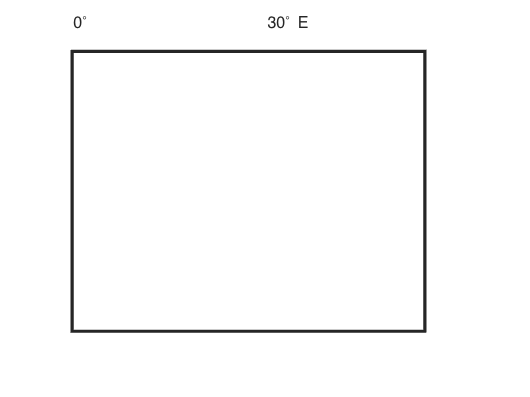

close
f1 = figure;
w = worldmap('world');
    axesm miller; 
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-75,-50]);
    setm(w, 'maplonlimit', [0,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 30);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'grid', 'off');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')

    scatterm(grid.cice_hist.lat,grid.cice_hist.lon,1)

Unable to resolve the name grid.cice_hist.lat.

    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    title('CICE history grid')


f2 = figure;
w = worldmap('world');
    axesm miller; 
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-75,-50]);
    setm(w, 'maplonlimit', [0,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 30);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'grid', 'off');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')

    scatterm(grid.cice_bathy.lat,grid.cice_bathy.lon,1)

Unrecognized field name "cice_bathy".

    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    title('CICE bathymetry grid')


f3 = figure;
w = worldmap('world');
    axesm miller; 
    setm(w, 'Origin', [90 0 0]);
    setm(w, 'maplatlimit', [60,90]);

    setm(w, 'maplonlimit', [0,360]);

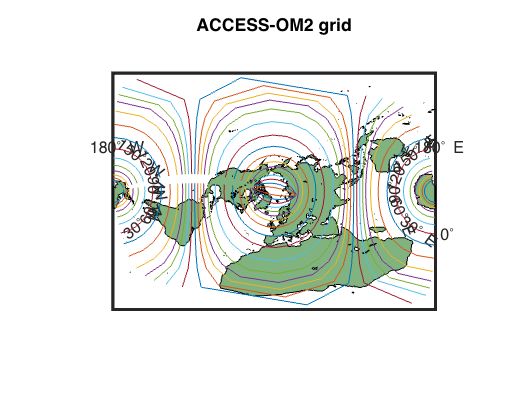

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 30);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'grid', 'off');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    plotm(grid.access.lat(1:10:end,1:10:end),grid.access.lon(1:10:end,1:10:end),10)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    title('ACCESS-OM2 grid')


f4 = figure;
w = worldmap('world');
    axesm miller; 
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-75,-50]);
    setm(w, 'maplonlimit', [0,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 30);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'grid', 'off');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    scatterm(grid.cice_hist.lat,grid.cice_hist.lon,1,'red')
    scatterm(grid.cice_bathy.lat,grid.cice_bathy.lon,1)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    title('Both CICE history (red) and bathymetry (blue) grids')


grid.cice_hist.angle = ncread('/Users/noahday/Github/cice-dirs/runs/test/history/iceh_ic.2005-01-01-03600.nc',"ANGLE");
f5 = figure;
w = worldmap('world');
    axesm eqaazim; 
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-90,90]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 30);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'grid', 'off');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(grid.cice_hist.lat,grid.cice_hist.lon,grid.cice_hist.angle)
    colorbar
    caxis([-1,1])
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    title('CICE ANGLE grid')


grid.cice_hist.ice = ncread('/Users/noahday/Github/cice-dirs/runs/test/history/iceh_ic.2005-01-01-03600.nc',"aice");
f6 = figure;
w = worldmap('world');
    axesm eqaazim; 
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 30);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'grid', 'off');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(grid.cice_hist.lat,grid.cice_hist.lon,grid.cice_hist.angle)
    colorbar
    caxis([-1,1])
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    title('CICE aice from using ACCESS-OM2 grid')
    



% Look at the ik11 forcing


ncdisp('/Users/noahday/GitHub/cice-dirs/input/CICE_data/forcing/om2/JRA55/1-4-0/vas_input4MIPs_atmosphericState_OMIP_MRI-JRA55-do-1-4-0_gr_201701010000-201712312100.nc')

Source:
           /Users/noahday/GitHub/cice-dirs/input/CICE_data/forcing/om2/JRA55/1-4-0/vas_input4MIPs_atmosphericState_OMIP_MRI-JRA55-do-1-4-0_gr_201701010000-201712312100.nc
Format:
           netcdf4_classic
Global Attributes:
           Conventions        = 'CF-1.7 CMIP-6.2'
           activity_id        = 'input4MIPs'
           cell_measures      = 'area: areacella'
           comment            = 'Based on JRA-55 reanalysis (1958-01 to 2019-01)'
           contact            = 'Hiroyuki Tsujino (htsujino@mri-jma.go.jp)'
           creation_date      = '2019-03-07T11:42:44Z'
           data_specs_version = '01.00.29'
           dataset_category   = 'atmosphericState'
           external_variables = 'areacella'
           frequency          = '3hrPt'
           further_info_url   = 'http://climate.mri-jma.go.jp/~htsujino/jra55do.html'
           grid               = 'data regridded to the normal atmosphere TL319 gaussian grid (320x640 latxlon) from a reduced TL319 gaussian grid

% prra - rainfall flux,  kg m^-2 s^-1
% prsn - Snowfall flux, kg m^-2 s^-1 (from CICE: total precipitation (3
% hourly average), fsnow) = ttlpcp
% huss - specific humidity = spchmd
% psl - air pressure, Pa = none
% rlds - surface downwelling longwave, W m^-2 = dlwsfc
% rsds - surface downwelling shortwave, W m^-2 = glbrad
% tas - air temp, K = airtmp
% ts - Surface temp, K = none
% uas - Eastward component of wind, m s^-1 = wndewd (check direction?)
% vas - Northward component of wind, m s^-1 = wndnwd (check direction?)
% time = time

% Look at JRA55 forcing
ncdisp('/Users/noahday/GitHub/cice-dirs/input/CICE_data/forcing/gx1/JRA55/8XDAILY/JRA55_03hr_forcing_2005.nc')

Source:
           /Users/noahday/GitHub/cice-dirs/input/CICE_data/forcing/gx1/JRA55/8XDAILY/JRA55_03hr_forcing_2005.nc
Format:
           classic
Global Attributes:
           history = 'Mon Aug  5 15:31:32 2019: ncks -v time,LON,LAT,glbrad,dlwsfc,wndewd,wndnwd,airtmp,spchmd,ttlpcp JRA55_03hr_forcing_20050101.00.netrad.nc JRA55_03hr_forcing_20050101.00.nc'
           NCO     = 'netCDF Operators version 4.7.5 (Homepage = http://nco.sf.net, Code = http://github.com/nco/nco)'
Dimensions:
           nj   = 384
           ni   = 320
           time = 2920  (UNLIMITED)
Variables:
    LAT   
           Size:       320x384
           Dimensions: ni,nj
           Datatype:   single
           Attributes:
                       long_name = 'Latitude'
                       units     = 'degrees_north'
    LON   
           Size:       320x384
           Dimensions: ni,nj
           Datatype:   single
           Attributes:
                       long_name = 'Longitude'
                       uni

% airtmp, ^
% dlwsfc, ^
% glbrad, ^
% spchmd, ^
% time, ^
% ttlpcp, ^
% wndewd, ^
% wndnwd, ^